UNIVERSIDAD INDUSTRIAL DE SANTANDER, COLOMBIA

NUMERICAL ANALYSIS

JORGE LUIS BACCA

2025

# *Laboratory 11: Numerical Integration*

## **Name: Alvaro Jose Martinez Castro**

## **Instructions:**

- Send the **.mlx** and **.m** files including the solution to each point of the practice with name ***Lab11_name_lastname.zip****.*

- You are allowed to use internet, notes, and .m files that you have created before.

## **Purposes:**

- To apply the numerical integration methods. 

- To implement the numerical integration methods in Matlab.

- To interpret problems which can be solved by the numerical integration methods.

- To propose problems in which the numerical integration methods can be used.

### Implementing

- **(1.0 points) **Create a Matlab function called *my_trapezoidal_function_name lastname() *to approximate an integral using the **composite trapezoidal rule**. The arguments of the function must be: the function to be integrated $f\left(x\right)\;$(as an inline function), the limits of integration [$a,b$], and the the value of $h$. 

            *Hint. Remember that the Trapezoidal rule is given by the formulation*

            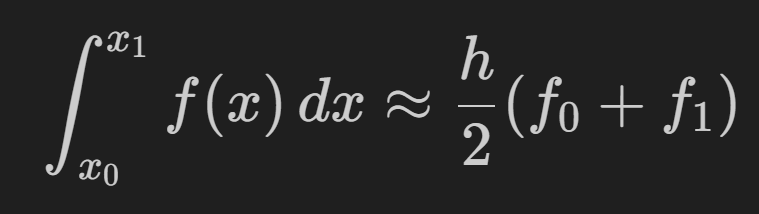

fun = @(x) 1 + exp(-x).*sin(4*x);
a = 0;
b = 1;
h = 1;
Integration1 = my_trapezoidal_function_martinez(fun, a, b, h);
disp(Integration1)

    0.8608



- **(1.0 points)** Create a Matlab function called *my_simpson_function_name_lastname() *to approximate an integral using the **composite Simpson’s rule**. The arguments of the function must be: the function to be integrated $f\left(x\right)\;$(as an inline function), the limits of integration [$a,b$], and the the value of $h$. 

            *Hint. Remember that the Simpson's rule is given by the formulation*

        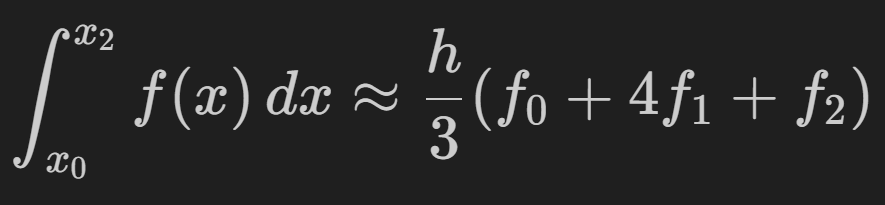

fun = @(x) 1 + exp(-x).*sin(4*x);
a = 0;
b = 1;
h = 0.5;
Integration2 = my_simpson_function_martinez(fun, a, b, h);
disp(Integration2)

    1.3213



- **(1.0 points)** Create a Matlab function called *my_boole_function_name_lastname() *to approximate an integral using the **composite Simpson’s rule**. The arguments of the function must be: the function to be integrated $f\left(x\right)\;$(as an inline function), the limits of integration [$a,b$], and the the value of $h$. 

            *Hint. Remember that the Boole's rule is given by the formulation*

        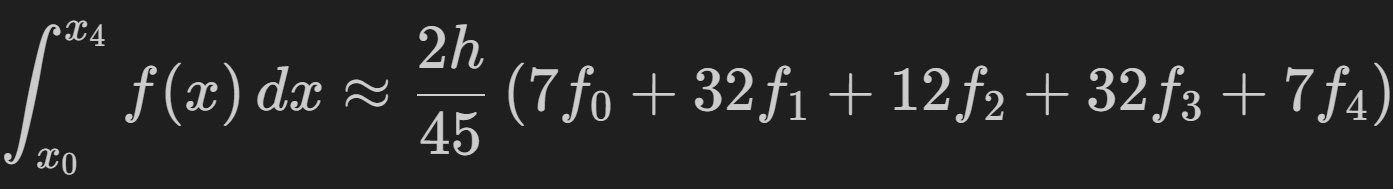

            Use the following values to test your function: $a=0,\;\;\;\;b=\pi ,\;\;\;h=\frac{\pi }{4}$

fun = @(x) sin(x);    % Puedes usar cualquier función inline aquí
a = 0;
b = pi;
h = pi/4;             % Paso, como indica el ejercicio
Integration2 = my_boole_function_martinez(fun, a, b, h);
disp(Integration2)

    1.9986



### Applying

- **(0.5 points) **Integrate $f\left(x\right)=\textrm{xln}\left(x\right)$ over [$1,2$] using the trapezoidal rule with step size $h=0\ldotp 25$. 

% Definir la función
f = @(x) x.*log(x);

% Definir los límites y el paso
a = 1;
b = 2;
h = 0.25;

% Crear los puntos de integración
x = a:h:b;
y = f(x);

% Aplicar la regla del trapecio compuesta
I = h*(sum(y) - 0.5*y(1) - 0.5*y(end));

% Mostrar el resultado
disp(I)

    0.6399



- **(0.5 points)** Integrate $f\left(x\right)=\textrm{xln}\left(x\right)$ over [$1,2$]  using the Simpson’s rule with step size $h=0\ldotp 25$.

% Definir la función
f = @(x) x.*log(x);

% Definir los límites y el paso
a = 1;
b = 2;
h = 0.25;

% Crear los puntos de integración
x = a:h:b;
y = f(x);
n = length(x) - 1; % Número de subintervalos

if mod(n,2) ~= 0
    error('El número de subintervalos debe ser par para Simpson');
end

% Aplicar la regla compuesta de Simpson
I = y(1) + y(end);
for i = 2:2:n
    I = I + 4*y(i);
end
for i = 3:2:n-1
    I = I + 2*y(i);
end
I = I * h/3;

% Mostrar el resultado
disp(I)

    0.6363



### Interpreting

**(1.0 points) **The probability that a machine fails in the process follows a normal distribution given 

 
$$f\left(t\right)=\left(\frac{1}{\sqrt{2\pi }}\right)e^{\frac{{-t}^2 }{2}}$$


The cumulative distribution to determine the probability to produce any amount of failures is then defined by 


$$\phi \left(x\right)=\frac{1}{2}+\left(\frac{1}{\sqrt{2\pi }}\right)\int_0^x e^{\frac{{-t}^2 }{2}}$$


Determine the probability that the machine produces 5 failures using the created functions for trapezoidal and Simpson’s rules. *Hint*. Use $h=5$. 

% Put your code here